clear

syms f(x) g h
f(x) = x

$$f(x) = x$$

g = sym(0)

$$g = 0$$

h = sym(0)

$$h = 0$$


nElem = 4

nElem = 4

elemDegree = 2

elemDegree = 2

elemContinuity = [-1 1 1 1 -1]

elemContinuity =     -1     1     1     1    -1




x = sym("x","real");
xMin = 0;
xMax = 1;

[eCONN,nodes] = generateMesh(xMin,xMax,nElem,elemDegree);

% Create the B-Spline
splineSpace.degree = elemDegree;
splineSpace.uniqueKnotsVector = linspace(xMin,xMax,nElem+1);
splineSpace.continuityVector = elemContinuity;
BSpline = bspline(splineSpace);
% Global Bezier Extraction Operator
M = BSpline.decomposition.globalExtractionOperator;
% Local Bezier Extraction Operators -- access as C{e}
C = BSpline.decomposition.localExtractionOperator;

% Create the local basis functions
bFun = basisFunction("Bernstein", elemDegree, sym("xi","real"), [-1 1]);
ELEM = createElements(BSpline,bFun);



figure
hold on

LN1 = C{1}*ELEM(1).LBasisFuns

$$LN1(xi) = \left(\begin{array}{c} \frac{{\left(\xi -1\right)}^{2}}{4}\\ \frac{{\left(\xi +1\right)}^{2}}{8}-\left(\frac{\xi }{2}-\frac{1}{2}\right)\,\left(\xi +1\right)\\ \frac{{\left(\xi +1\right)}^{2}}{8} \end{array}\right)$$

LN1 = symfun(LN1,symvar(LN1));
GN1 = LN1(ELEM(1).GlobalVariate_to_LocalVariate)

$$GN1 = \left(\begin{array}{c} \frac{{\left(8\,x-2\right)}^{2}}{4}\\ 8\,x^{2}-8\,x\,\left(4\,x-1\right)\\ 8\,x^{2} \end{array}\right)$$

fplot(GN1,ELEM(1).GDomain,'b')

LN2 = C{2}*ELEM(2).LBasisFuns

$$LN2(xi) = \left(\begin{array}{c} \frac{{\left(\xi -1\right)}^{2}}{8}\\ \frac{{\left(\xi -1\right)}^{2}}{8}+\frac{{\left(\xi +1\right)}^{2}}{8}-\left(\frac{\xi }{2}-\frac{1}{2}\right)\,\left(\xi +1\right)\\ \frac{{\left(\xi +1\right)}^{2}}{8} \end{array}\right)$$

LN2 = symfun(LN2,symvar(LN2));
GN2 = LN2(ELEM(2).GlobalVariate_to_LocalVariate)

$$GN2 = \left(\begin{array}{c} \frac{{\left(8\,x-4\right)}^{2}}{8}\\ \frac{{\left(8\,x-2\right)}^{2}}{8}+\frac{{\left(8\,x-4\right)}^{2}}{8}-\left(4\,x-2\right)\,\left(8\,x-2\right)\\ \frac{{\left(8\,x-2\right)}^{2}}{8} \end{array}\right)$$

fplot(GN2,ELEM(2).GDomain,'r')

LN3 = C{3}*ELEM(3).LBasisFuns

$$LN3(xi) = \left(\begin{array}{c} \frac{{\left(\xi -1\right)}^{2}}{8}\\ \frac{{\left(\xi -1\right)}^{2}}{8}+\frac{{\left(\xi +1\right)}^{2}}{8}-\left(\frac{\xi }{2}-\frac{1}{2}\right)\,\left(\xi +1\right)\\ \frac{{\left(\xi +1\right)}^{2}}{8} \end{array}\right)$$

LN3 = symfun(LN3,symvar(LN3));
GN3 = LN3(ELEM(3).GlobalVariate_to_LocalVariate)

$$GN3 = \left(\begin{array}{c} \frac{{\left(8\,x-6\right)}^{2}}{8}\\ \frac{{\left(8\,x-4\right)}^{2}}{8}+\frac{{\left(8\,x-6\right)}^{2}}{8}-\left(4\,x-3\right)\,\left(8\,x-4\right)\\ \frac{{\left(8\,x-4\right)}^{2}}{8} \end{array}\right)$$

fplot(GN3,ELEM(3).GDomain,'g')

LN4 = C{4}*ELEM(4).LBasisFuns

$$LN4(xi) = \left(\begin{array}{c} \frac{{\left(\xi -1\right)}^{2}}{8}\\ \frac{{\left(\xi -1\right)}^{2}}{8}-\left(\frac{\xi }{2}-\frac{1}{2}\right)\,\left(\xi +1\right)\\ \frac{{\left(\xi +1\right)}^{2}}{4} \end{array}\right)$$

LN4 = symfun(LN4,symvar(LN4));
GN4 = LN4(ELEM(4).GlobalVariate_to_LocalVariate)

$$GN4 = \left(\begin{array}{c} \frac{{\left(8\,x-8\right)}^{2}}{8}\\ \frac{{\left(8\,x-8\right)}^{2}}{8}-\left(4\,x-4\right)\,\left(8\,x-6\right)\\ \frac{{\left(8\,x-6\right)}^{2}}{4} \end{array}\right)$$

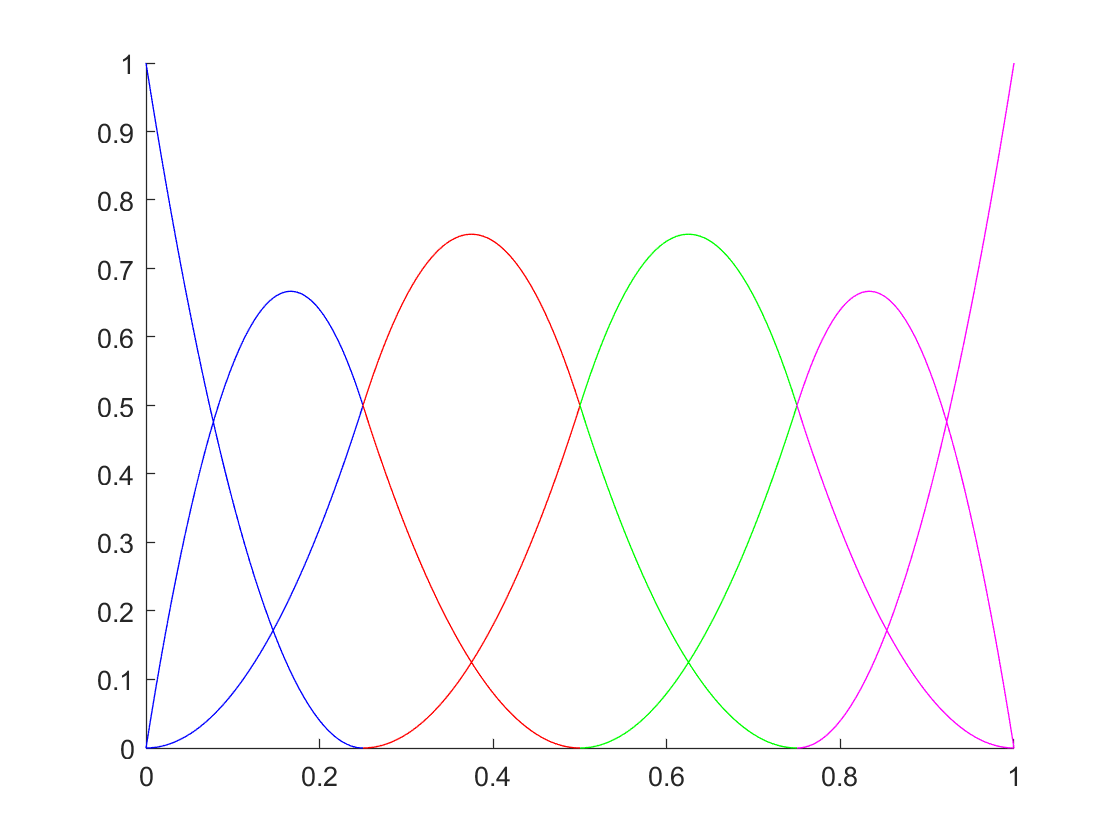

fplot(GN4,ELEM(4).GDomain,'m')

dGN1 = diff(GN1)

$$dGN1 = \left(\begin{array}{c} 32\,x-8\\ 8-48\,x\\ 16\,x \end{array}\right)$$

dGN2 = diff(GN2)

$$dGN2 = \left(\begin{array}{c} 16\,x-8\\ 12-32\,x\\ 16\,x-4 \end{array}\right)$$

dGN3 = diff(GN3)

$$dGN3 = \left(\begin{array}{c} 16\,x-12\\ 20-32\,x\\ 16\,x-8 \end{array}\right)$$

dGN4 = diff(GN4)

$$dGN4 = \left(\begin{array}{c} 16\,x-16\\ 40-48\,x\\ 32\,x-24 \end{array}\right)$$


k1 = [int(dGN1(1)*dGN1(1),[0 1/4]), int(dGN1(1)*dGN1(2),[0 1/4]), int(dGN1(1)*dGN1(3),[0 1/4]);...
    int(dGN1(2)*dGN1(1),[0 1/4]), int(dGN1(2)*dGN1(2),[0 1/4]), int(dGN1(2)*dGN1(3),[0 1/4]);...
    int(dGN1(3)*dGN1(1),[0 1/4]), int(dGN1(3)*dGN1(2),[0 1/4]), int(dGN1(3)*dGN1(3),[0 1/4])]

$$k1 = \left(\begin{array}{ccc} \frac{16}{3} & -4 & -\frac{4}{3}\\ -4 & 4 & 0\\ -\frac{4}{3} & 0 & \frac{4}{3} \end{array}\right)$$


k2 = [int(dGN2(1)*dGN2(1),[1/4 1/2]), int(dGN2(1)*dGN2(2),[1/4 1/2]), int(dGN2(1)*dGN2(3),[1/4 1/2]);...
    int(dGN2(2)*dGN2(1),[1/4 1/2]), int(dGN2(2)*dGN2(2),[1/4 1/2]), int(dGN2(2)*dGN2(3),[1/4 1/2]);...
    int(dGN2(3)*dGN2(1),[1/4 1/2]), int(dGN2(3)*dGN2(2),[1/4 1/2]), int(dGN2(3)*dGN2(3),[1/4 1/2])]

$$k2 = \left(\begin{array}{ccc} \frac{4}{3} & -\frac{2}{3} & -\frac{2}{3}\\ -\frac{2}{3} & \frac{4}{3} & -\frac{2}{3}\\ -\frac{2}{3} & -\frac{2}{3} & \frac{4}{3} \end{array}\right)$$


k3 = [int(dGN3(1)*dGN3(1),[1/2 3/4]), int(dGN3(1)*dGN3(2),[1/2 3/4]), int(dGN3(1)*dGN3(3),[1/2 3/4]);...
    int(dGN3(2)*dGN3(1),[1/2 3/4]), int(dGN3(2)*dGN3(2),[1/2 3/4]), int(dGN3(2)*dGN3(3),[1/2 3/4]);...
    int(dGN3(3)*dGN3(1),[1/2 3/4]), int(dGN3(3)*dGN3(2),[1/2 3/4]), int(dGN3(3)*dGN3(3),[1/2 3/4])]

$$k3 = \left(\begin{array}{ccc} \frac{4}{3} & -\frac{2}{3} & -\frac{2}{3}\\ -\frac{2}{3} & \frac{4}{3} & -\frac{2}{3}\\ -\frac{2}{3} & -\frac{2}{3} & \frac{4}{3} \end{array}\right)$$


k4 = [int(dGN4(1)*dGN4(1),[3/4 1]), int(dGN4(1)*dGN4(2),[3/4 1]), int(dGN4(1)*dGN4(3),[3/4 1]);...
    int(dGN4(2)*dGN4(1),[3/4 1]), int(dGN4(2)*dGN4(2),[3/4 1]), int(dGN4(2)*dGN4(3),[3/4 1]);...
    int(dGN4(3)*dGN4(1),[3/4 1]), int(dGN4(3)*dGN4(2),[3/4 1]), int(dGN4(3)*dGN4(3),[3/4 1])]

$$k4 = \left(\begin{array}{ccc} \frac{4}{3} & 0 & -\frac{4}{3}\\ 0 & 4 & -4\\ -\frac{4}{3} & -4 & \frac{16}{3} \end{array}\right)$$

K = sym(zeros(length(BSpline.nodes)));
gID = BSpline.elementConnectivity(:,1)

gID =      1
     2
     3


K(gID,gID) = K(gID,gID) + k1

$$K = \left(\begin{array}{cccccc} \frac{16}{3} & -4 & -\frac{4}{3} & 0 & 0 & 0\\ -4 & 4 & 0 & 0 & 0 & 0\\ -\frac{4}{3} & 0 & \frac{4}{3} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


gID = BSpline.elementConnectivity(:,2)

gID =      2
     3
     4


K(gID,gID) = K(gID,gID) + k2

$$K = \left(\begin{array}{cccccc} \frac{16}{3} & -4 & -\frac{4}{3} & 0 & 0 & 0\\ -4 & \frac{16}{3} & -\frac{2}{3} & -\frac{2}{3} & 0 & 0\\ -\frac{4}{3} & -\frac{2}{3} & \frac{8}{3} & -\frac{2}{3} & 0 & 0\\ 0 & -\frac{2}{3} & -\frac{2}{3} & \frac{4}{3} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


gID = BSpline.elementConnectivity(:,3)

gID =      3
     4
     5


K(gID,gID) = K(gID,gID) + k3

$$K = \left(\begin{array}{cccccc} \frac{16}{3} & -4 & -\frac{4}{3} & 0 & 0 & 0\\ -4 & \frac{16}{3} & -\frac{2}{3} & -\frac{2}{3} & 0 & 0\\ -\frac{4}{3} & -\frac{2}{3} & 4 & -\frac{4}{3} & -\frac{2}{3} & 0\\ 0 & -\frac{2}{3} & -\frac{4}{3} & \frac{8}{3} & -\frac{2}{3} & 0\\ 0 & 0 & -\frac{2}{3} & -\frac{2}{3} & \frac{4}{3} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


gID = BSpline.elementConnectivity(:,4)

gID =      4
     5
     6


K(gID,gID) = K(gID,gID) + k4

$$K = \left(\begin{array}{cccccc} \frac{16}{3} & -4 & -\frac{4}{3} & 0 & 0 & 0\\ -4 & \frac{16}{3} & -\frac{2}{3} & -\frac{2}{3} & 0 & 0\\ -\frac{4}{3} & -\frac{2}{3} & 4 & -\frac{4}{3} & -\frac{2}{3} & 0\\ 0 & -\frac{2}{3} & -\frac{4}{3} & 4 & -\frac{2}{3} & -\frac{4}{3}\\ 0 & 0 & -\frac{2}{3} & -\frac{2}{3} & \frac{16}{3} & -4\\ 0 & 0 & 0 & -\frac{4}{3} & -4 & \frac{16}{3} \end{array}\right)$$

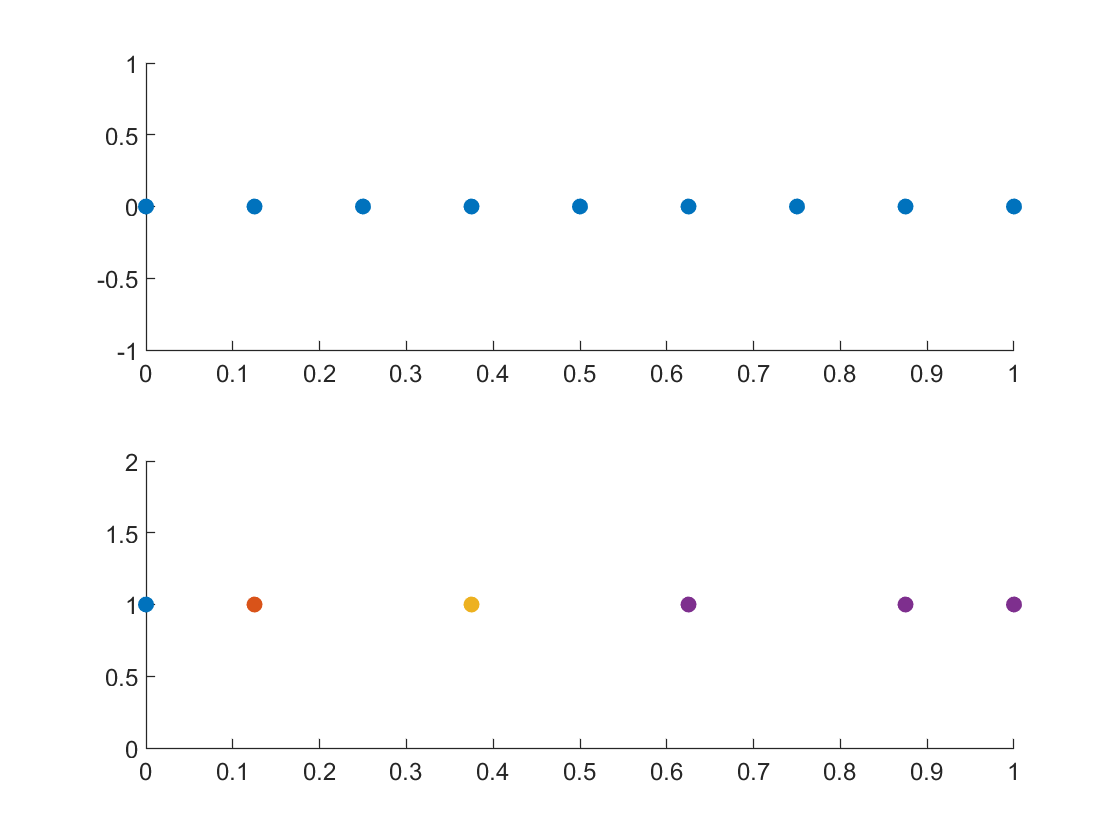

sNodes = 1×1 cell array
    {3×1 sym}


sNodes = 1×2 cell array
    {3×1 sym}    {3×1 sym}


sNodes = 1×3 cell array
    {3×1 sym}    {3×1 sym}    {3×1 sym}


sNodes = 1×4 cell array
    {3×1 sym}    {3×1 sym}    {3×1 sym}    {3×1 sym}



figure
% Plot Bezier nodes
subplot(2,1,1)
scatter(nodes,zeros(size(nodes)),'o','filled')
% Plot Spline nodes
subplot(2,1,2)
hold on
for e = 1:4
    sNodes{e} = inv(C{e}') * nodes(eCONN(:,e))'
    scatter(sNodes{e},ones(size(sNodes{e})),'o','filled')
end


size(M)

ans =      6     9


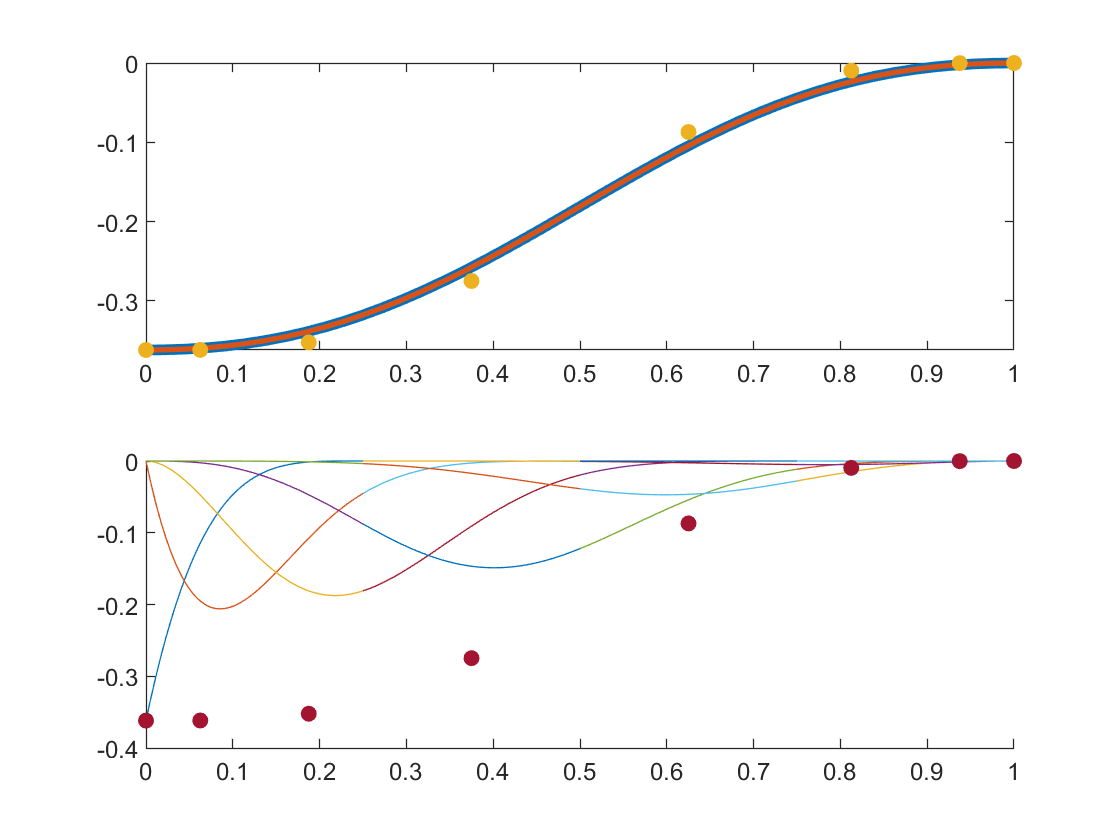

clear

syms f(x) g h
f(x) = -sin(x*2*pi)-cos(x*pi);
g = sym(0);
h = sym(0);

E = computeExactSolution(f,g,h);
FE = main(4, 4, [-1 3 3 3 -1], f, g, h);

figure
subplot(2,1,1)
fplot(E.U,[0 1],'LineWidth',4)
hold on
fplot(FE.U,[0 1],'LineWidth',2)
scatter(FE.Spline.nodes,FE.LinearSystem.d,'o','filled')

subplot(2,1,2)
hold on
C = FE.Spline.decomposition.localExtractionOperator;
for e = 1:FE.Spline.numcells
    N = C{e}*FE.Spline.decomposition.spline.basis.functions(FE.Spline.decomposition.localExtractionSupportedBezierBases{e});
    locBasisFuns = FE.Spline.decomposition.localExtractionSupportedSplineBases{e};
    for ii = 1:length(locBasisFuns)
        fplot(N(ii)*FE.LinearSystem.d(locBasisFuns(ii)),FE.Elements(e).GDomain)
    end
end
scatter(FE.Spline.nodes,FE.LinearSystem.d,'o','filled')